## **8QAM**

clc
close all
clear all


%Valor de a y b
a=0.541;
b=1.307;

% -------------- SECUENCIA DE BITS - ----------
fdn = randi([0 1],255,1);
fdn=fdn';
n=1:3400;


%-------GRÁFICA DE LA SECUENCIA GENERADA  -------------------

figure(1)
h=tiledlayout(2,1)

h =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [2 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


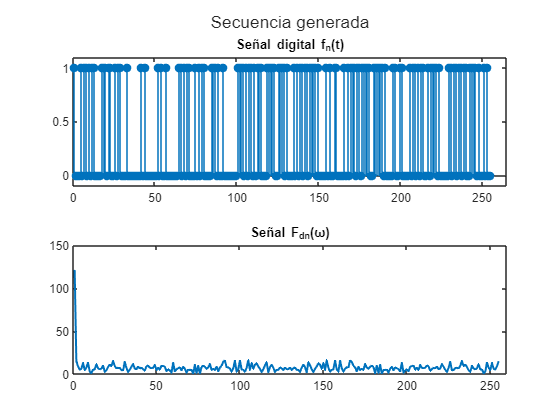

title(h,'Secuencia generada');
nexttile
stem(fdn,'filled')
axis([0 265 -0.1 1.1])
title('Señal digital f_n(t)')
nexttile
plot(abs(fft(fdn)),'LineWidth',1.5)
title('Señal F_{dn}(\omega)')
xlim([0 260])

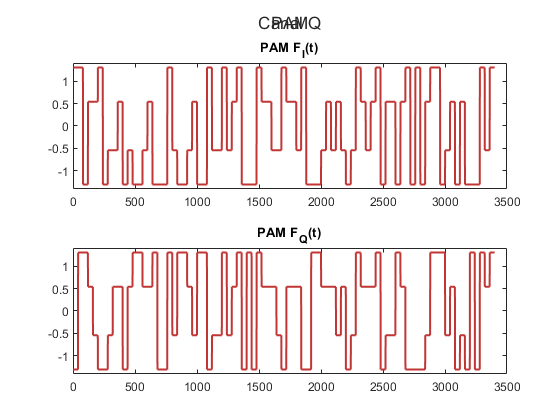




%------------------- CONVERTIDOR DE 2 A 4 NIVELES -----------------------

FI =[];
FQ =[];
for i=1:3:length(fdn)-1
         I=fdn(1,i);
         Q=fdn(1,i+1);
         C=fdn(1,i+2);
         
         %------PARA I
         switch num2str(([I C]))
            case '0  0'
                FI=[FI, ones(1,40)*a*-1];
            case '0  1'
                FI=[FI ,ones(1,40)*b*-1];
            case '1  0'
                FI=[FI ,ones(1,40)*a];
            case '1  1'
                FI=[FI ,ones(1,40)*b];
         end

         %------PARA Q

         switch num2str(([Q C]))
            case '0  0'
                FQ=[FQ, ones(1,40)*a*-1];
            case '0  1'
                FQ=[FQ ,ones(1,40)*b*-1];
            case '1  0'
                FQ=[FQ ,ones(1,40)*a];
            case '1  1'
                FQ=[FQ ,ones(1,40)*b];
        end
          
          
     
end

figure(2)
w=tiledlayout(2,1);
title(w,'PAM')
nexttile
plot(FI,'Color','#C13535','LineWidth',1.5)
ylim([-b-0.1 b+0.1])
title("PAM F_I(t)")
nexttile
plot(FQ,'Color','#C13535','LineWidth',1.5);
title("PAM F_Q(t)")
ylim([-b-0.1 b+0.1])

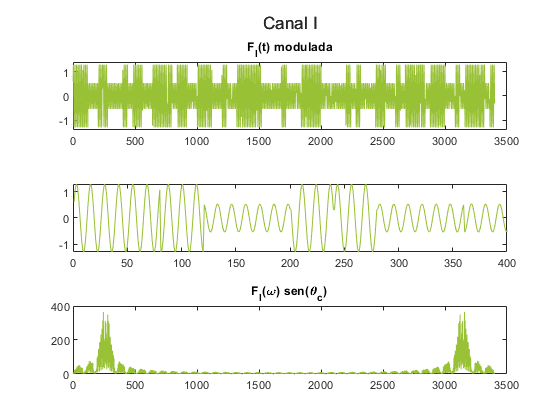



%---------- MODULACIÓN ----------------------

p1=sin(2*pi*n*(1/13));
p2=cos(2*pi*n*(1/13));

PAM1= FI.*p1; %Canal I
PAM2= FQ.*p2; %Canal Q

figure(3)
t=tiledlayout(3,1);
title(t,'Canal I')
nexttile
plot(PAM1,'Color','#98C135')
ylim([-b-0.1 b+0.1])
title('F_I(t) modulada')
nexttile
plot(PAM1,'Color','#98C135')
xlim([0 400])
nexttile
plot(abs(fft(PAM1)),'Color','#98C135')
title('F_I(\omega) sen(\theta_c)')

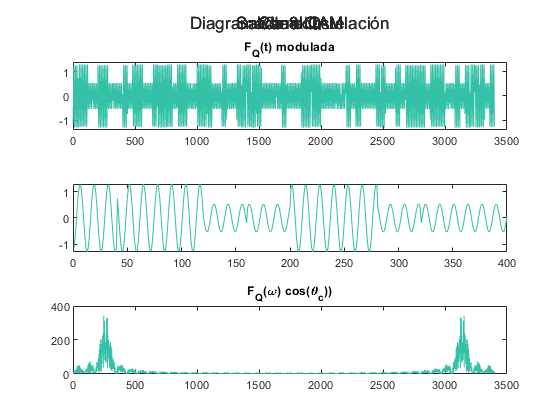



figure(4)
q=tiledlayout(3,1);
title(q,'Canal Q')
nexttile
plot(PAM2,'Color','#35C1A7')
ylim([-b-0.1 b+0.1])
title('F_Q(t) modulada')
nexttile
plot(PAM2,'Color','#35C1A7')
xlim([0 400])
nexttile
plot(abs(fft(PAM2)),'Color','#35C1A7')
title('F_Q(\omega) cos(\theta_c))')

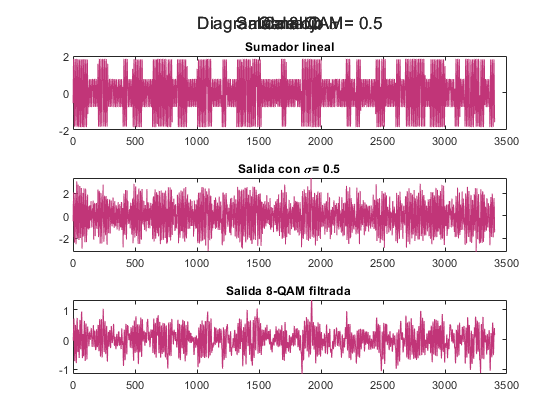


%--------- SALIDA 8-QAM --------------

Suma= PAM1+PAM2;
Ruido=Suma+randn(1,length(n))*0.5;

%------------FILTRO PASABANDA -----------
wc=1/20; % Frecuencia de corte del filtro debería ser menor que la portadora
[N,D] = butter(1,wc,'low');
Salida8QAM=filter(N,D,Ruido); %sigma=0.5

figure(5)
f=tiledlayout(3,1);
title(f,'Salida 8-QAM')
nexttile
plot(Suma,'Color','#C13578')
title('Sumador lineal')
nexttile
plot(Ruido,'Color','#C13578')
title('Salida con \sigma= 0.5')
nexttile
plot(Salida8QAM,'Color','#C13578')
title('Salida 8-QAM filtrada ')

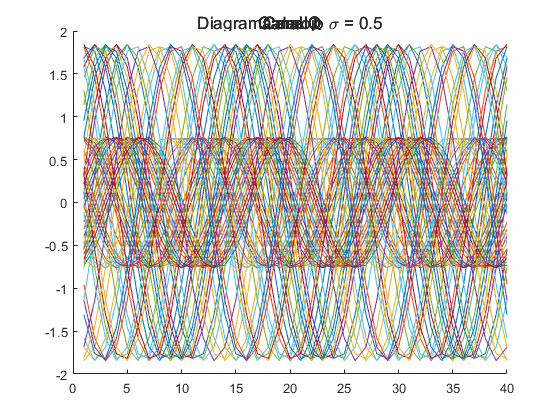



%----- DIAGRAMA DE OJO -----------
figure(6)
z=tiledlayout(2,1);
title(z,'Diagrama de ojo \sigma = 0.5');
k=length(Suma);
for j=1:40:k-40
    for i=1:40
        ojo(i)=Suma(j+i-1);   
    end
    hold on
    plot(ojo)
end
nexttile

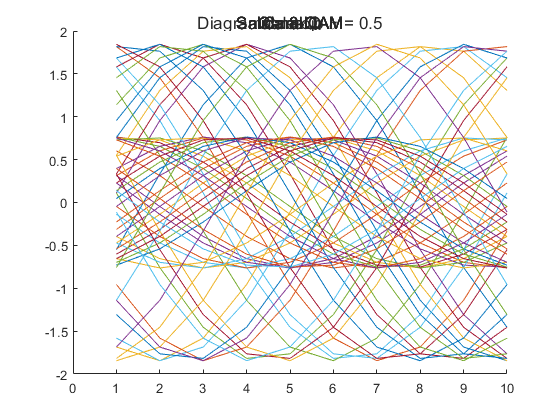

for j=1:40:k-40
    for i=1:40
        ojo(i)=Suma(j+i-1);   
    end
    hold on
    plot(ojo)
end
xlim([0,10])

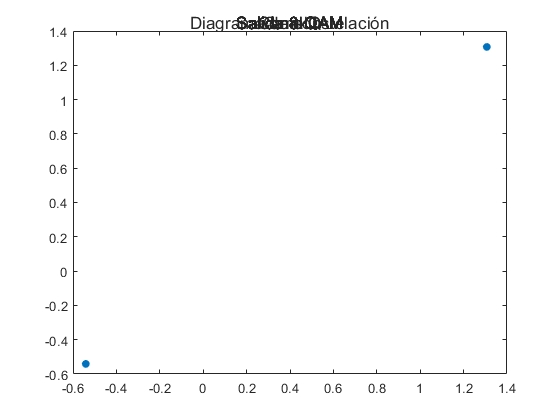





%---------- RECEPTOR 8QAM -----------------

%DEMODULACIÓN 
demFI=cad( Salida8QAM.*sin(2*pi*n/13));
demFQ = cad(Salida8QAM.*cos(2*pi*n/13));

FIrec=[];
FQrec=[];

% De acuerdo con la documentación de MatLab

AvI=cad(demFI);
AvQ=cad(demFQ);


for i=1:2:85-1
    FIrec=[FIrec Detector(AvI(i),AvI(i+1)) ];
    FQrec=[FQrec Detector(AvQ(i),AvQ(i+1)) ];
end


figure(7)
m=tiledlayout('flow');
title(m,'Diagrama de constelación');
plot(FIrec, FQrec ,'.','markersize', 20)

function detec = cad(x)
k=length(x);
detec = zeros(1,85);
r=1;

    for j=0:40:k-40
        avera=0;
        for i=1:40
          avera= avera+x(j+i);
        end
        avera=avera/40;
         if avera <= 0 
             detec(r)= 0;
         else
             detec(r)= 1;
         end    
        r=r+1;
    end
end
 
function nv = Detector(x,y)
a=0.541;
b=1.307;
nv = 0;
    if x == 0 && y == 0
        nv = -a;
    else
        if x == 0 && y == 1
            nv = -b;
        else
            if x == 1 && y == 0
                nv = a;
            else
                if x == 1 && y == 1
                    nv = b;
                end
            end
        end
    end
    return 
end



% rxData = qamdemod(Salida8QAM.*exp(-1i*pi/13),8);
% % Generate the reference constellation points.
% refpts = qammod((0:7)',8) .* exp(1i*pi/8);
% 
% figure(7)
% plot(Salida8QAM(rxData==0),'g.');
% hold on
% plot(Salida8QAM(rxData==3),'c.');
% plot(refpts,'r*')
% text(real(refpts)+0.1,imag(refpts),num2str((0:7)'))
% xlabel('In-Phase')
% ylabel('Quadrature')
% legend('Points corresponding to 0','Points corresponding to 3', ...
%     'Reference constellation','location','nw');
% % e